# Load data

% file processing 

currentDir = pwd;

fileInput = 'wsrpet_nrm2018baseline1_bfsrtm_BP.nii';
fileMask = 'grey_matter_mask.nii'

fileMask = 'grey_matter_mask.nii'


% input data
dataFolder = fullfile(currentDir, '..', '..', '..', '..', 'data', 'health', 'pet', ...
    '1_session_neuroimaging_basics', 'nii_data');

inputDataPath = fullfile(dataFolder, fileInput);

% mask data
maskFolder = fullfile(currentDir, 'data', 'mask');
maskDataPath = fullfile(maskFolder, fileMask);

disp(inputDataPath);

C:\Users\marku\OneDrive\Documents\MATLAB\healthcare\brain\main\..\..\..\..\data\health\pet\1_session_neuroimaging_basics\nii_data\wsrpet_nrm2018baseline1_bfsrtm_BP.nii


disp(maskDataPath);

C:\Users\marku\OneDrive\Documents\MATLAB\healthcare\brain\main\data\mask\grey_matter_mask.nii


## Load the header of a PET image using spm_vol function (PATH).


% Input
V_pet = spm_vol(inputDataPath);
img_pet = spm_read_vols(V_pet);

% mask
V_mask = spm_vol(maskDataPath);
mask = spm_read_vols(V_mask);

% check mask functionality
disp (unique(mask))

     0
     1



## Create a masked PET image by assigning zero to each voxel autside the grey matter mask.

% Initialize image matrix
% Sekect grey matter voxel values (BPs) from the original PET image and store them into the same places into the masked image matrix

img_pet_masked = zeros(size(img_pet)); 
img_pet_masked(logical(mask)) = img_pet(logical(mask)); 

% Save the masked PET image using the V_pet header and spm_ write_volfunction 
% (IMPORTANT! Change the fname in the header. Otherwise you will overwrite the original image.).

V_pet.fname = [currentDir, '/data/results/wsrpet_nrm2018baseline1_bfsrtm_BP_masked.nii']; 
spm_write_vol(V_pet,img_pet_masked); 

## plotting the original and masked data

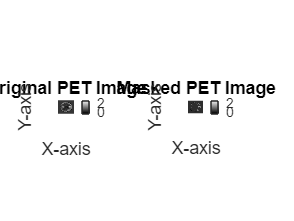

% Initialize figure
figure;

% Choose the slice index you want to visualize (e.g., slice number 50)
slice_index = 50;

% Plot the original PET image
subplot(1, 2, 1);
imshow(img_pet(:,:,slice_index), []);
title('Original PET Image');
xlabel('X-axis');
ylabel('Y-axis');
colorbar; % Display color bar for intensity scale

% Plot the masked PET image
subplot(1, 2, 2);
imshow(img_pet_masked(:,:,slice_index), []);
title('Masked PET Image');
xlabel('X-axis');
ylabel('Y-axis');
colorbar; % Display color bar for intensity scale

## calling it as a function

clear;

currentDir = pwd;

fileInput = 'wsrpet_nrm2018baseline1_bfsrtm_BP.nii';
fileMask = 'grey_matter_mask.nii'

fileMask = 'grey_matter_mask.nii'


% input data
dataFolder = fullfile(currentDir, '..', '..', '..', '..', 'data', 'health', 'pet', ...
    '1_session_neuroimaging_basics', 'nii_data');

% mask data
maskFolder = fullfile(currentDir, 'data', 'mask');

maskDataPath = fullfile(maskFolder, fileMask);

% output destination
outputStore = ['/data/results/'];

[V_pet, img_pet_masked] =  maskAndPlotPET(dataFolder, fileInput, ...
    maskDataPath, outputStore);